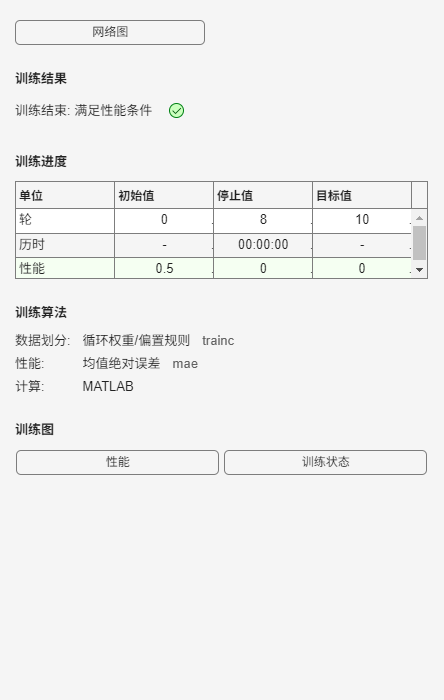

% 1. 定义训练数据
P = [ ...
  1 1 1 0 1 1 0 1 1 0 ;  % p1
  1 1 1 1 1 0 1 1 0 1 ;  % p2
  1 1 1 0 1 1 0 1 1 0 ;  % p3
  1 0 1 1 1 0 1 1 1 1 ;  % p4
  0 1 0 1 1 1 1 1 1 0 ;  % p5
  1 0 1 1 0 1 0 0 0 1 ;  % p6
  1 0 0 0 0 1 1 0 0 0 ;  % p7
  1 1 1 1 1 0 1 1 1 1 ;  % p8
  0 1 1 0 1 1 1 1 1 1 ;  % p9
  1 1 0 1 0 1 1 0 0 0 ;  % p10
  0 1 1 0 1 1 1 1 0 1 ;  % p11
  0 0 1 0 0 0 0 1 1 1 ;  % p12
  1 1 0 1 1 1 1 1 1 1 ;  % p13
  1 1 1 1 0 0 0 1 1 1 ;  % p14
  1 1 1 0 1 1 1 1 1 0 ]; % p15

T = [1 0 1 0 1 0 1 0 1 0];   % 偶数=1，奇数=0

% 2. 创建感知器并训练
mm = minmax(P);         % 输入范围
net = newp(mm,1);       % 单输出感知器
net.trainParam.epochs = 10;   % 限制最多训练10个epoch
net = train(net,P,T);   % 训练


% 3. 定义测试模式 (15 x 2)
ptest = [1 1 1 1 0 1 1 0 1 1 0 1 1 0 1;   % pattern 1
         1 1 0 0 1 0 0 1 1 0 1 0 1 1 1];  % pattern 2

% 注意：ptest 需要转置，变成 15x2，每列一个样本
ptest = ptest';

% 4. 测试感知器输出
Ytest = sim(net, ptest);

% 打印结果
disp('测试模式输出：');

测试模式输出：


disp(Ytest);

     1     0

